clc
clear
disp("Initilization Procedure")

Initilization Procedure


model.Parameters
param = control.calculateOperatingPoint(param);

Calculate Operating Point for T_a = 293.150000 [K]

param = model.calculateModel(param);

Calculate bilinear model matrices
Calculate linearisation decoupled
Calculate linearisation coupled
Testing controlability
Testing T_ref


param = model.calculateWDelta(param,0);

## Same real uncertainty for every input


$$\Delta=\delta \textbf{I}, \delta\in[-1,1]$$


param = control.DesignProcedureWeightedRealUncertainties(param,0,{[-1,1]});

Evaluation of design procedure for weighted real uncertainties 
Q is positive definite


ans =     0.1488    0.1501    0.1507    0.1524    0.4953    0.4956    0.4967    0.5027    2.0767    2.0784    2.0786    2.0797


Eigenvalues of the decoupled systems are all negative 


ans =   -3.7108 + 0.0000i  -0.4990 + 0.3691i  -0.4990 - 0.3691i  -3.7661 + 0.0000i  -0.4919 + 0.3704i  -0.4919 - 0.3704i  -3.7411 + 0.0000i  -0.4906 + 0.3708i  -0.4906 - 0.3708i  -3.6805 + 0.0000i  -0.5067 + 0.3712i  -0.5067 - 0.3712i


Eigenvalues of the coupled systems are all negative 


ans =   -3.3341 + 0.0000i  -2.5737 + 0.6961i  -2.5737 - 0.6961i  -2.5819 + 0.5111i  -2.5819 - 0.5111i  -2.5300 + 0.3182i  -2.5300 - 0.3182i  -1.3232 + 0.0000i  -0.5680 + 0.0000i  -0.4929 + 0.0000i  -0.4845 + 0.0000i  -0.4811 + 0.0000i


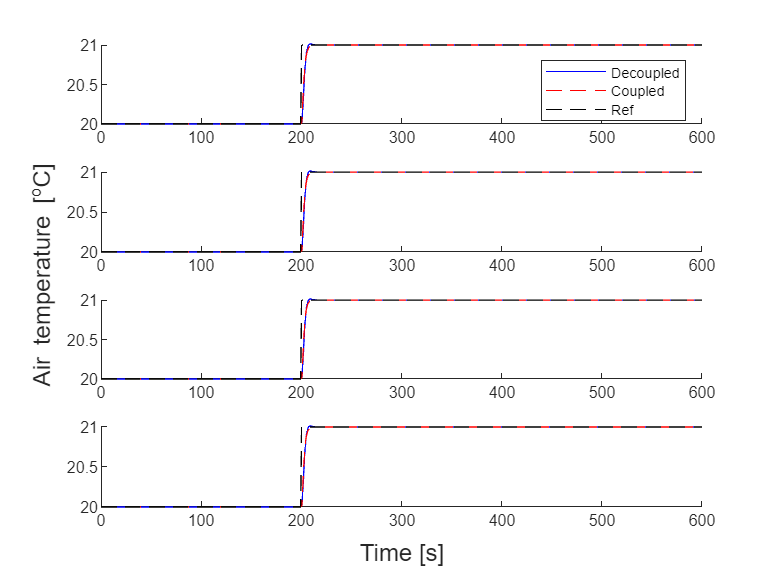

util.SimulateLinearStep(param, "Examination_Weighted_Real_Uncertainties_Identical",0);

## Individual real uncertainty for every input


$$\Delta= 
\left[\matrix{\delta_1 & 0 & 0 & 0 \cr 0 & \delta_2 & 0 & 0 \cr
0 & 0 & \delta_3 & 0 \cr 0 & 0 & 0 & \delta_4}\right], \qquad \delta_i \in [-1,1], \quad i=1,2,3,4$$


param = control.DesignProcedureWeightedRealUncertainties(param,0,{[-1,1],[-1,1],[-1,1],[-1,1]});

Evaluation of design procedure for weighted real uncertainties 
Q is positive definite


ans =     0.1074    0.1076    0.1088    0.1103    0.4828    0.4926    0.4952    0.5014    2.5992    2.5995    2.6019    2.6098


Eigenvalues of the decoupled systems are all negative 


ans =   -4.2863 + 0.0000i  -0.4231 + 0.3651i  -0.4231 - 0.3651i  -4.3050 + 0.0000i  -0.4103 + 0.3746i  -0.4103 - 0.3746i  -4.2598 + 0.0000i  -0.4089 + 0.3761i  -0.4089 - 0.3761i  -4.2304 + 0.0000i  -0.4187 + 0.3792i  -0.4187 - 0.3792i


Eigenvalues of the coupled systems are all negative 


ans =   -4.5112 + 0.0000i  -4.7548 + 0.0000i  -4.8551 + 0.0000i  -4.8102 + 0.0000i  -1.0726 + 0.0000i  -1.1373 + 0.0000i  -1.1791 + 0.0000i  -0.6761 + 0.2408i  -0.6761 - 0.2408i  -0.5866 + 0.0000i  -0.5616 + 0.0000i  -0.5676 + 0.0000i


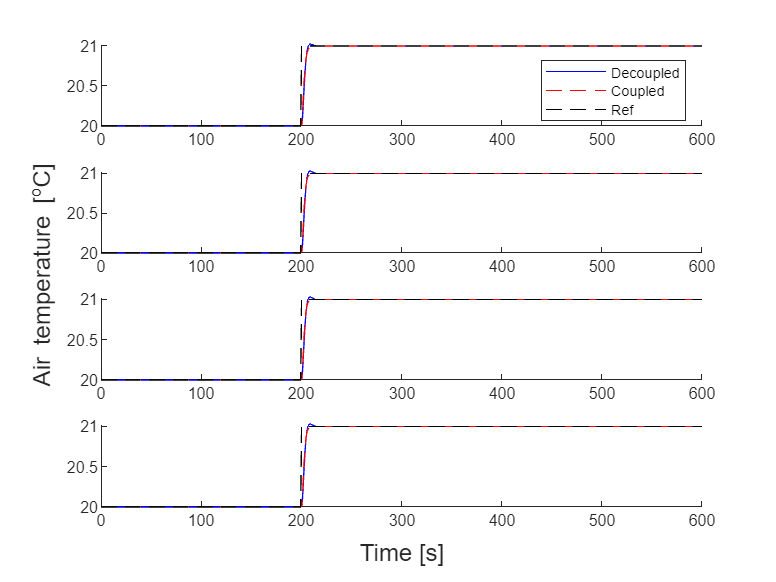

util.SimulateLinearStep(param, "Examination_Weighted_Real_Uncertainties_Individual",0);